## Optimization v3 — Adding interpolation and plots

#### Newton's method, using interpolation to find the initial guess based on E0(0), E0(1), E0'(0), and E0'(1).

% profile on;

clc; clear;  % Clear the command window and workspace

%% System Parameters
N = 2;          % Number of quadrature nodes (for Gauss-Hermite integration)
SNR = 5;         % Signal-to-Noise Ratio
M = 2;          % Size of the PAM constellation (number of symbols)
d = 2;           % Distance parameter (spacing between constellation points)
R = 0.5;         % Communication rate

%% Compute Gauss-Hermite Nodes and Weights
% These are used for numerical integration over a Gaussian density.
[nodes, weights] = GaussHermite_Locations_Weights(N)

nodes =   -0.707106781186548
   0.707106781186547


weights =    0.886226925452758
   0.886226925452758



%% Generate and Normalize PAM Constellation
% Create a PAM constellation with M symbols and spacing d.
X = generatePAMConstellation(M, d);
% Normalize the constellation so that its average energy is 1.
X = X / sqrt(mean(X.^2));

%% Initialize the Probability Distribution for Constellation Symbols
% Create a column vector where each symbol has equal probability (1/M).
Q = repmat(1/M, 1, M);
Q = Q';

%% Define the Gaussian Function
G = @(z) exp(-abs(z).^2) / pi;

%% Create Required Matrices for Computation
pi_matrix = createPiMatrix(M, N, weights);
z_matrix = createComplexNodesMatrix(nodes);
g_matrix = createGMatrix(X, z_matrix, SNR, G);

%% Find an Initial Guess for the Optimization
% Compute E0 (a performance metric) and its derivative at the endpoints rho=0 and rho=1.
E00 = 0;   % E0 at rho=0
E01 = computeEoForRhoExponential(1, Q, pi_matrix, g_matrix);   % E0 at rho=1
E0P0 = computeFirstDerivativeE0(Q, pi_matrix, g_matrix, 0);     % Derivative at rho=0
E0P1 = computeFirstDerivativeE0(Q, pi_matrix, g_matrix, 1);     % Derivative at rho=1

% Use Hermite interpolation to obtain a candidate starting point for optimization.
rho_star = demoHermiteInterpolation(E00, E0P0, E01, E0P1, R);

                   0   0.499999170195996   0.001104947436006  -0.001878972358028

Approx. max of G(rho) is 0.499225 at rho = 1.0000



%% Set Optimization Parameters
tol = 1e-7;           % Convergence tolerance

%% Use Newton's Method to Find the Optimal rho
% The goal is to maximize E0(rho) - rho*R.
tic;  % Start the overall timer

if R > E0P0
    % If the communication rate is higher than the derivative at 0,
    % the maximum is at rho = 0.
    rho_opt = 0;
    E0_max = 0;
elseif R < E0P1
    % If the communication rate is lower than the derivative at 1,
    % the maximum is at rho = 1.
    rho_opt = 1;
    E0_max = computeEoForRhoExponential(rho_opt, Q, pi_matrix, g_matrix) - R;
else
    % Otherwise, use Newton's method starting from rho_star to find the optimum.
    tic;  % Start timer for the Newton optimization
    
    % [rho_opt, E0_max] = optimizationNewton(Q, pi_matrix, g_matrix, R, tol, rho_star);   
end

%% Display the Results
fprintf('rho_opt = %.6f\n', rho_opt);

rho_opt = 1.000000


fprintf('E0_max = %.6f\n', E0_max);

E0_max = 0.499225


fprintf('Optimisation time: %.2f ms\n', round(toc * 1000));

Optimisation time: 3.00 ms



% profile viewer;

#### Newton's method, using the initial guess rho = 0.5, but using the correct second derivative

clc; clear;  % Clear the command window and workspace

%% System Parameters
N = 10;          % Number of quadrature nodes (for Gauss-Hermite integration)
SNR = 1;         % Signal-to-Noise Ratio
M = 1024;          % Size of the PAM constellation (number of symbols)
d = 2;           % Distance parameter (spacing between constellation points)
R = 0.5;         % Communication rate

%% Compute Gauss-Hermite Nodes and Weights
% These are used for numerical integration over a Gaussian density.
[nodes, weights] = GaussHermite_Locations_Weights(N);

%% Generate and Normalize PAM Constellation
% Create a PAM constellation with M symbols and spacing d.
X = generatePAMConstellation(M, d);

% Normalize the constellation so that its average energy is 1.
X = X / sqrt(mean(X.^2));

%% Initialize the Probability Distribution for Constellation Symbols
% Create a column vector where each symbol has equal probability (1/M).
Q = repmat(1/M, 1, M);
Q = Q';

%% Define the Gaussian Function
G = @(z) exp(-abs(z).^2) / pi;

%% Create Required Matrices for Computation
pi_matrix = createPiMatrix(M, N, weights);
z_matrix = createComplexNodesMatrix(nodes);
g_matrix = createGMatrix(X, z_matrix, SNR, G);

% Use rho_star = 0.5 as a default starting point
rho_star = 0.5;

%% Set Optimization Parameters
tol = 1e-4;           % Convergence tolerance

%% Use Newton's Method to Find the Optimal rho
% The goal is to maximize E0(rho) - rho*R.
tic;  % Start the overall timer

% Use Newton's method starting from rho_star to find the optimum.
[rho_opt, E0_max] = optimizationNewton(Q, pi_matrix, g_matrix, R, tol, rho_star);

   0.500000000000000

   0.534893808240825


Newton algorithm finished after 2 iterations.



%% Display the Results
fprintf('rho_opt = %.6f\n', rho_opt);

rho_opt = 0.535529


fprintf('E0_max = %.6f\n\n', E0_max);

E0_max = 0.334666



fprintf('Optimisation time: %.2f ms\n', round(toc * 1000));

Optimisation time: 9960.00 ms


## Gradient descent

Approx. max of G(rho) is 0.0684 at rho = 0.5321


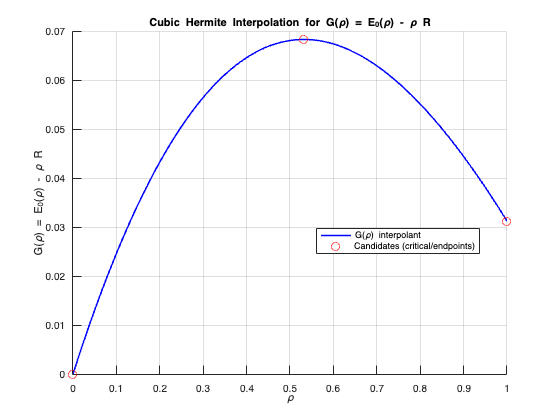

clc; clear;  % Clear the command window and workspace

%% System Parameters
N = 10;          % Number of quadrature nodes (for Gauss-Hermite integration)
SNR = 1;         % Signal-to-Noise Ratio
M = 1024;          % Size of the PAM constellation (number of symbols)
d = 2;           % Distance parameter (spacing between constellation points)
R = 0.5;         % Communication rate

%% Compute Gauss-Hermite Nodes and Weights
% These are used for numerical integration over a Gaussian density.
[nodes, weights] = GaussHermite_Locations_Weights(N);

%% Generate and Normalize PAM Constellation
% Create a PAM constellation with M symbols and spacing d.
X = generatePAMConstellation(M, d);
% Normalize the constellation so that its average energy is 1.
X = X / sqrt(mean(X.^2));

%% Initialize the Probability Distribution for Constellation Symbols
% Create a column vector where each symbol has equal probability (1/M).
Q = repmat(1/M, 1, M);
Q = Q';

%% Define the Gaussian Function
G = @(z) exp(-abs(z).^2) / pi;

%% Create Required Matrices for Computation
pi_matrix = createPiMatrix(M, N, weights);
z_matrix = createComplexNodesMatrix(nodes);
g_matrix = createGMatrix(X, z_matrix, SNR, G);

%% Find an Initial Guess for the Optimization
% Compute E0 (a performance metric) and its derivative at the endpoints rho=0 and rho=1.
E00 = computeEoForRhoExponential(0, Q, pi_matrix, g_matrix);   % E0 at rho=0
E01 = computeEoForRhoExponential(1, Q, pi_matrix, g_matrix);   % E0 at rho=1
E0P0 = computeFirstDerivativeE0(Q, pi_matrix, g_matrix, 0);     % Derivative at rho=0
E0P1 = computeFirstDerivativeE0(Q, pi_matrix, g_matrix, 1);     % Derivative at rho=1

% Use Hermite interpolation to obtain a candidate starting point for optimization.
rho_star = demoHermiteInterpolation(E00, E0P0, E01, E0P1, R);


%% Set Optimization Parameters
tol = 1e-7;           % Convergence tolerance

%% Use Newton's Method to Find the Optimal rho
% The goal is to maximize E0(rho) - rho*R.
tic;  % Start the overall timer

if R > E0P0
    % If the communication rate is higher than the derivative at 0,
    % the maximum is at rho = 0.
    rho_opt = 0;
elseif R < E0P1
    % If the communication rate is lower than the derivative at 1,
    % the maximum is at rho = 1.
    rho_opt = 1;
else
    % Otherwise, use Newton's method starting from rho_star to find the optimum.
    tic;  % Start timer for the Newton optimization
    [rho_opt, E0_max] = optimizationGradientDescent(Q, pi_matrix, g_matrix, R, tol, rho_star);   
end

iter = 1, rho = 0.532144, F0 = 2.494110e+00, dF0 = -8.666354e-01, d2F0 = 9.648944e-01
gradient = 1.297335e-03, curvature = -3.839471e-01, alpha = 2.604525e+00
iter = 2, rho = 0.535523, F0 = 2.491187e+00, dF0 = -8.633834e-01, d2F0 = 9.599474e-01
gradient = 2.216746e-06, curvature = -3.826360e-01, alpha = 2.613450e+00
iter = 3, rho = 0.535529, F0 = 2.491182e+00, dF0 = -8.633779e-01, d2F0 = 9.599390e-01
gradient = 6.497469e-12, curvature = -3.826337e-01, alpha = 2.613465e+00

Gradient Ascent finished after 3 iterations.
rho_opt = 0.535529
E0_max = 0.334666




%% Display the Results
fprintf('rho_opt = %.6f\n', rho_opt);

rho_opt = 0.535529


fprintf('E0_max = %.6f\n\n', E0_max);

E0_max = 0.334666



fprintf('Optimisation time: %.2f ms\n', round(toc * 1000));

Optimisation time: 10628.00 ms


#### fminsearch method, using interpolation to find the initial guess based on E0(0), E0(1), E0'(0), and E0'(1).

clc; clear;  % Clear the command window and workspace

%% System Parameters
N = 20;          % Number of quadrature nodes (for Gauss-Hermite integration)
SNR = 1;         % Signal-to-Noise Ratio
M = 128;          % Size of the PAM constellation (number of symbols)
d = 2;           % Distance parameter (spacing between constellation points)
R = 0.5;         % Communication rate

%% Compute Gauss-Hermite Nodes and Weights
% These are used for numerical integration over a Gaussian density.
[nodes, weights] = GaussHermite_Locations_Weights(N);

%% Generate and Normalize PAM Constellation
% Create a PAM constellation with M symbols and spacing d.
X = generatePAMConstellation(M, d);
% Normalize the constellation so that its average energy is 1.
X = X / sqrt(mean(X.^2));

%% Initialize the Probability Distribution for Constellation Symbols
% Create a column vector where each symbol has equal probability (1/M).
Q = repmat(1/M, 1, M);
Q = Q';

%% Define the Gaussian Function
G = @(z) exp(-abs(z).^2) / pi;

%% Create Required Matrices for Computation
pi_matrix = createPiMatrix(M, N, weights);
z_matrix = createComplexNodesMatrix(nodes);
g_matrix = createGMatrix(X, z_matrix, SNR, G);

%% Find an Initial Guess for the Optimization
% Compute E0 (a performance metric) and its derivative at the endpoints rho=0 and rho=1.
E00 = computeEoForRhoExponential(0, Q, pi_matrix, g_matrix);   % E0 at rho=0
E01 = computeEoForRhoExponential(1, Q, pi_matrix, g_matrix);   % E0 at rho=1
E0P0 = computeFirstDerivativeE0(Q, pi_matrix, g_matrix, 0);     % Derivative at rho=0
E0P1 = computeFirstDerivativeE0(Q, pi_matrix, g_matrix, 1);     % Derivative at rho=1

% Use Hermite interpolation to obtain a candidate starting point for optimization.
rho_star = demoHermiteInterpolation(E00, E0P0, E01, E0P1, R);

Approx. max of G(rho) is 0.0684 at rho = 0.5322



%% Set Optimization Parameters
tol = 1e-7;           % Convergence tolerance

%% Use Newton's Method to Find the Optimal rho
% The goal is to maximize E0(rho) - rho*R.
tic;  % Start the overall timer

if R > E0P0
    % If the communication rate is higher than the derivative at 0,
    % the maximum is at rho = 0.
    rho_opt = 0;
elseif R < E0P1
    % If the communication rate is lower than the derivative at 1,
    % the maximum is at rho = 1.
    rho_opt = 1;
else
    % Otherwise, use Newton's method starting from rho_star to find the optimum.
    tic;  % Start timer for the Newton optimization
    [rho_opt, E0_max] = optimizeRho_fminsearch(Q', pi_matrix, g_matrix, R, rho_star);
end

%% Display the Results
fprintf('rho_opt = %.6f\n', rho_opt);
fprintf('E0_max = %.6f\n\n', E0_max);
fprintf('Optimisation time: %.2f ms\n', round(toc * 1000));